Code for 2b

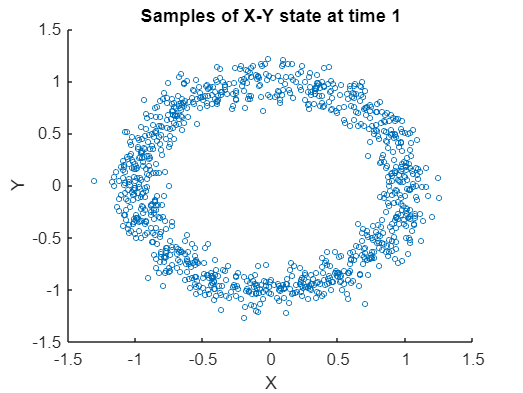

% Given mean and covariance
mean_initial = [0; 0; 0];
covariance_initial = [0.01 0 0; 0 0.01 0; 0 0 10000];

% Generate samples from the Gaussian distribution
initial_samples = mvnrnd(mean_initial, covariance_initial, 1000);
% Given time step
delta_t = 1; % Assume distance covered in one time step is 1

% Initialize array to store propagated states
p1 = zeros(1000, 3);

% Propagate each sample according to the motion equation
for i = 1:1000
    x_k = initial_samples(i, 1);
    y_k = initial_samples(i, 2);
    theta_k = initial_samples(i, 3);
    
    x_k1 = x_k + delta_t * cos(theta_k);
    y_k1 = y_k + delta_t * sin(theta_k);
    
    p1(i, :) = [x_k1, y_k1, theta_k];
end
% Plot x-y state samples at time 1
scatter(p1(:, 1), p1(:, 2), 10);
xlabel('X');
ylabel('Y');
title('Samples of X-Y state at time 1');

Code for 2c

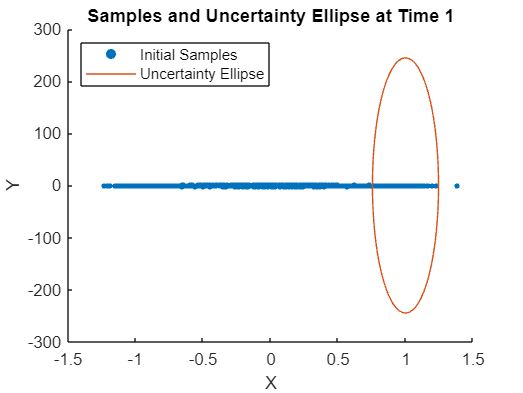

% Given mean and covariance for initial samples (from previous code)
mean_initial = [0; 0; 0];
covariance_initial = [0.01 0 0; 0 0.01 0; 0 0 10000];

% Generate samples from the Gaussian distribution
initial_samples = mvnrnd(mean_initial, covariance_initial, 1000);

% Given time step
delta_t = 1; % Assume distance covered in one time step is 1

% Initialize array to store propagated states
p1 = zeros(1000, 3);

% Propagate each sample according to the motion equation
for i = 1:1000
    x_k = initial_samples(i, 1);
    y_k = initial_samples(i, 2);
    theta_k = initial_samples(i, 3);
    
    x_k1 = x_k + delta_t * cos(theta_k);
    y_k1 = y_k + delta_t * sin(theta_k);
    
    p1(i, :) = [x_k1, y_k1, theta_k];
end

% Compute the predicted mean and covariance at time 1 using EKF prediction step (as previously shown)

% Plotting the points (samples) and the uncertainty ellipse
scatter(p1(:, 1), p1(:, 2), 10, 'filled'); % Blue points for initial samples
hold on;

% Plot the uncertainty ellipse for the predicted state at time 1
plotErrorEllipse(x_bar_1(1:2), Sigma_bar_1(1:2, 1:2), 0.95); % Assuming 95% confidence level
xlabel('X');
ylabel('Y');
title('Samples and Uncertainty Ellipse at Time 1');
legend('Initial Samples', 'Uncertainty Ellipse', 'Location','northwest');
hold off;

Code for 2d

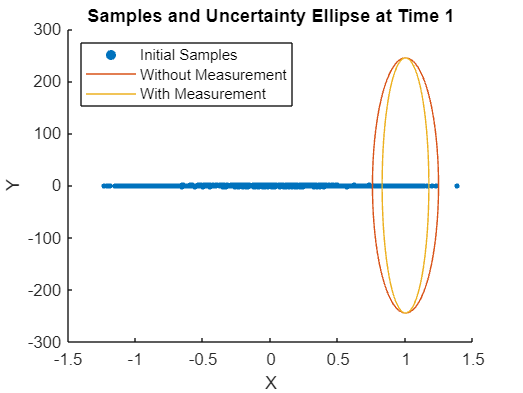

% Given measurement and measurement noise
z_1 = 1; % Actual measurement at time 1
measurement_noise_covariance = 0.01;

% Compute Kalman gain
H_1 = [1, 0, 0]; % Measurement Jacobian
K_1 = Sigma_bar_1 * H_1' / (H_1 * Sigma_bar_1 * H_1' + measurement_noise_covariance);

% Update state estimate
x_hat_1 = x_bar_1 + K_1 * (z_1 - sqrt(x_bar_1(1)^2 + x_bar_1(2)^2)); % Measurement update

% Update covariance
Sigma_1 = (eye(3) - K_1 * H_1) * Sigma_bar_1;

% Plotting the points (samples), the uncertainty ellipse before measurement update, and after incorporating measurement
scatter(p1(:, 1), p1(:, 2), 10, 'filled'); % Blue points for initial samples
hold on;

% Plot the uncertainty ellipse before measurement update
plotErrorEllipse(x_bar_1(1:2), Sigma_bar_1(1:2, 1:2), 0.95); % Before measurement update

% Incorporate measurement and plot the updated uncertainty ellipse
plotErrorEllipse(x_hat_1(1:2), Sigma_1(1:2, 1:2), 0.95); % After measurement update

xlabel('X');
ylabel('Y');
title('Samples and Uncertainty Ellipse at Time 1');
legend('Initial Samples', 'Without Measurement', 'With Measurement', 'Location', 'northwest');
hold off;